# 5.1

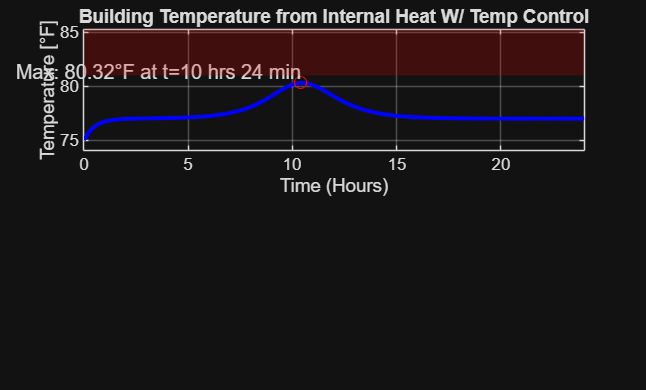

% //////////////////////////////////////////////////// 
% (RUN ONE SECTION AT A TIME OR CHANGE VAIRABLE NAMES)
% ////////////////////////////////////////////////////

% rk4_internal_heat_w_ac.m
clc;
clear;

% Parameters
T0 = 75;                    % Initial temperature
t0 = 0;                     % Initial time
tf = 24;                    % Final time
dt = 0.1;                   % Time step
N = floor((tf - t0)/dt);    % Number of steps

% Time vector
t = t0:dt:tf;
T = zeros(1, length(t));    % Preallocate solution
T(1) = T0;                  % Initial condition

% Define internal heat source H(t)
H = @(t, T) 7 * sech((3/4)*(t - 10)) + 2 * (77 - T);    % Heat from people/lights/machines
%          ^^^  Change first value to modify input heat sources

% Define derivative function dT/dt
dTdt = @(t, T) H(t, T);          % No losses, only accumulation

% RK4 Integration
for i = 1:N
    ti = t(i);
    Ti = T(i);

    k1 = dt * dTdt(ti, Ti);
    k2 = dt * dTdt(ti + dt/2, Ti + k1/2);
    k3 = dt * dTdt(ti + dt/2, Ti + k2/2);
    k4 = dt * dTdt(ti + dt, Ti + k3);

    T(i+1) = Ti + (1/6)*(k1 + 2*k2 + 2*k3 + k4);
end

% Find and display max temperature and when it occurs
[max_T, idx_max] = max(T);      % Max value and its index
time_max_T = t(idx_max);        % Time at which max occurs

% Convert time to duration
time_duration = duration(floor(time_max_T), mod(time_max_T*60, 60), 0); % Convert to hours and minutes

% Plot the result
figure;
y_max = max_T + 5; 

% Plot temperature T(t)
subplot(2, 1, 1);
plot(t, T, 'b-', 'LineWidth', 2);
xlabel('Time (Hours)');
ylabel('Temperature [°F]');
title('Building Temperature from Internal Heat W/ Temp Control');
xlim([0 24]);        % Fix x-axis to 0–24 hours
ylim([min(T)-1, y_max]);  % Pad lower limit slightly for visibility
grid on;

% Add text to the graph where max temp occurs
hold on; % Keep the current plot
plot(time_max_T, max_T, 'ro'); % Mark the max temperature point
time_hours = floor(time_max_T); % Get the integer hours
time_minutes = round((time_max_T - time_hours) * 60); % Round minutes to nearest integer
text(time_max_T, max_T, sprintf('Max: %.2f°F at t=%d hrs %d min', max_T, time_hours, time_minutes), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold off; % Release the plot

% Add a red area to denote unsafe temps
hold on;
y_fill = 81 * ones(size(t));
y_max = max(T) + 5; 
fill([t, fliplr(t)], [y_fill, y_max * ones(size(t))], ...
     'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
hold off;


% Display constant temperature
time = 15;
for time = 15:24
    disp(T(time));
    time = time + 1;
end

   76.8862

   76.9090

   76.9277

   76.9432

   76.9561

   76.9669

   76.9759

   76.9836

   76.9901

   76.9957



## 5.2 (RUN ONE SECTION AT A TIME OR CHANGE VAIRABLE NAMES)

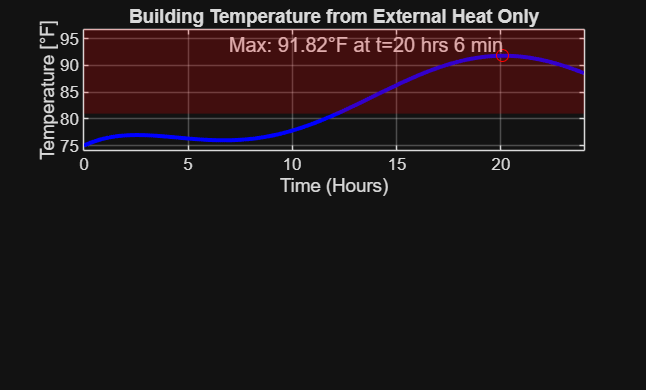

% Parameters
T0 = 75;                    % Initial temperature
t0 = 0;                     % Initial time
tf = 24;                    % Final time
dt = 0.1;                   % Time step
N = floor((tf - t0)/dt);    % Number of steps

% Time vector
t = t0:dt:tf;
T = zeros(1, length(t));    % Preallocate solution
T(1) = T0;                  % Initial condition

% Define internal heat source H(t)
H = @(t, T) 0.25 * (85 - 10 * cos((pi * (t - 5) / 12)) - T);    % Heat from people/lights/machines
%          ^^^  Change first value to modify input heat sources

% Define derivative function dT/dt
dTdt = @(t, T) H(t, T);          % No losses, only accumulation

% RK4 Integration
for i = 1:N
    ti = t(i);
    Ti = T(i);

    k1 = dt * dTdt(ti, Ti);
    k2 = dt * dTdt(ti + dt/2, Ti + k1/2);
    k3 = dt * dTdt(ti + dt/2, Ti + k2/2);
    k4 = dt * dTdt(ti + dt, Ti + k3);

    T(i+1) = Ti + (1/6)*(k1 + 2*k2 + 2*k3 + k4);
end

% Find and display max temperature and when it occurs
[max_T, idx_max] = max(T);      % Max value and its index
time_max_T = t(idx_max);        % Time at which max occurs

% Convert time to duration
time_duration = duration(floor(time_max_T), mod(time_max_T*60, 60), 0); % Convert to hours and minutes

% Plot the result
figure;
y_max = max_T + 5; 

% Plot temperature T(t)
subplot(2, 1, 1);
plot(t, T, 'b-', 'LineWidth', 2);
xlabel('Time (Hours)');
ylabel('Temperature [°F]');
title('Building Temperature from External Heat Only');
xlim([0 24]);        % Fix x-axis to 0–24 hours
ylim([min(T)-1, y_max]);  % Pad lower limit slightly for visibility
grid on;

% Add text to the graph where max temp occurs
hold on; % Keep the current plot
plot(time_max_T, max_T, 'ro'); % Mark the max temperature point
time_hours = floor(time_max_T); % Get the integer hours
time_minutes = round((time_max_T - time_hours) * 60); % Round minutes to nearest integer
text(time_max_T, max_T, sprintf('Max: %.2f°F at t=%d hrs %d min', max_T, time_hours, time_minutes), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold off; % Release the plot

% Add a red area to denote unsafe temps
hold on;
y_fill = 81 * ones(size(t));
y_max = max(T) + 5; 
fill([t, fliplr(t)], [y_fill, y_max * ones(size(t))], ...
     'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
hold off;


% Time (hours & minutes when damage begins)
T_alert = 81;
T_dmg = interp1(T, t, T_alert);  % Function that gives the time when T crosses 81

% Damage time in hours and minutes
hrs_dmg  = floor(T_dmg);
mins_dmg = round((T_dmg - hrs_dmg) * 60);
fprintf('Damage begins at %d hrs %02d min\n', hrs_dmg, mins_dmg); % Display

Damage begins at 12 hrs 09 min


## 5.3

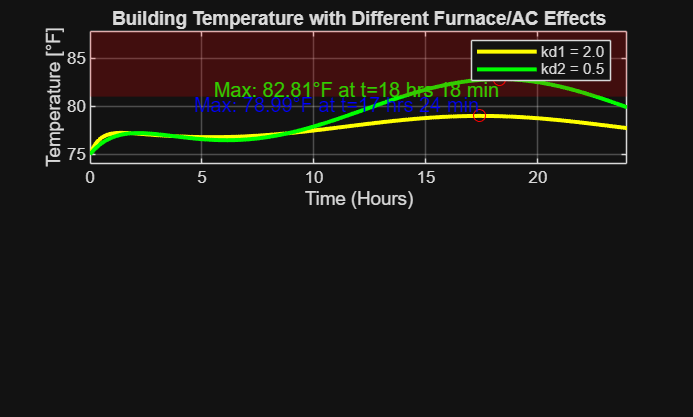

% Parameters
T0 = 75;                    % Initial temperature
t0 = 0;                     % Initial time
tf = 24;                    % Final time
dt = 0.1;                   % Time step
N = floor((tf - t0)/dt);    % Number of steps
kd1 = 2;                    % Effect of furnaces and ACs
kd2 = .5;

% Time vector
t = t0:dt:tf;
T1 = zeros(1, length(t));   % Preallocate solution for kd1
T2 = zeros(1, length(t));   % Preallocate solution for kd2
T1(1) = T0;                 % Initial condition for kd1
T2(1) = T0;                 % Initial condition for kd2

% Define internal heat source H(t)
H1 = @(t, T) 0.25 * (85 - 10 * cos((pi * (t - 5) / 12)) - T) + kd1*(77 - T);    % Heat from people/lights/machines, including effect of furnaces & ACs
%          ^^^  Change first value to modify input heat sources
H2 = @(t, T) 0.25 * (85 - 10 * cos((pi * (t - 5) / 12)) - T) + kd2*(77 - T);

% Define derivative function dT/dt
dT1dt = @(t, T) H1(t, T);   
dT2dt = @(t, T) H2(t, T);  

% RK4 Integration (merged loop for kd1 and kd2)
for i = 1:N
    ti = t(i);

    % kd1 
    Ti1 = T1(i);
    k1_1 = dt * dT1dt(ti, Ti1);
    k2_1 = dt * dT1dt(ti + dt/2, Ti1 + k1_1/2);
    k3_1 = dt * dT1dt(ti + dt/2, Ti1 + k2_1/2);
    k4_1 = dt * dT1dt(ti + dt, Ti1 + k3_1);
    T1(i+1) = Ti1 + (1/6)*(k1_1 + 2*k2_1 + 2*k3_1 + k4_1);

    % kd2 
    Ti2 = T2(i);
    k1_2 = dt * dT2dt(ti, Ti2);
    k2_2 = dt * dT2dt(ti + dt/2, Ti2 + k1_2/2);
    k3_2 = dt * dT2dt(ti + dt/2, Ti2 + k2_2/2);
    k4_2 = dt * dT2dt(ti + dt, Ti2 + k3_2);
    T2(i+1) = Ti2 + (1/6)*(k1_2 + 2*k2_2 + 2*k3_2 + k4_2);
end

% Find and display max temperature for kd1
[max_T1, idx_max1] = max(T1);      % Max value and its index
time_max_T1 = t(idx_max1);         % Time at which max occurs

% Find and display max temperature for kd2
[max_T2, idx_max2] = max(T2);      % Max value and its index
time_max_T2 = t(idx_max2);         % Time at which max occurs

% Plot the result
figure;
y_max = max([max_T1, max_T2]) + 5; 

% Plot temperature T(t)
subplot(2, 1, 1);
plotT1 = plot(t, T1, 'y-', 'LineWidth', 2); hold on;
plotT2 = plot(t, T2, 'g-', 'LineWidth', 2);
xlabel('Time (Hours)');
ylabel('Temperature [°F]');
title('Building Temperature with Different Furnace/AC Effects');
xlim([0 24]);        % Fix x-axis to 0–24 hours
ylim([min([T1,T2])-1, y_max]);  % Pad lower limit slightly for visibility
grid on;

% Add text to the graph where max temps occur
plot(time_max_T1, max_T1, 'ro'); % Mark the max temperature point for kd1
time_hours1 = floor(time_max_T1); % Get the integer hours
time_minutes1 = round((time_max_T1 - time_hours1) * 60); % Round minutes to nearest integer
text(time_max_T1, max_T1, sprintf('Max: %.2f°F at t=%d hrs %d min', max_T1, time_hours1, time_minutes1), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'b');

plot(time_max_T2, max_T2, 'ro'); % Mark the max temperature point for kd2
time_hours2 = floor(time_max_T2); % Get the integer hours
time_minutes2 = round((time_max_T2 - time_hours2) * 60); % Round minutes to nearest integer
text(time_max_T2, max_T2, sprintf('Max: %.2f°F at t=%d hrs %d min', max_T2, time_hours2, time_minutes2), ...
    'VerticalAlignment', 'top', 'HorizontalAlignment', 'right', 'Color', 'g');
hold off; % Release the plot

% Add a red area to denote unsafe temps
hold on;
y_fill = 81 * ones(size(t));
fill([t, fliplr(t)], [y_fill, y_max * ones(size(t))], ...
     'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
hold off;

legend([plotT1 plotT2], sprintf('kd1 = %.1f', kd1), sprintf('kd2 = %.1f', kd2));


% Equipment is only exposed to unsafe temps if kd = 0.5, so we'll concentrate on its plot

t_dmg = sum(T2 > 81) * dt;        % total hours
t_dmg_min = t_dmg * 60;           % total minutes

disp("The equipment was exposed to damaging temperature for " + t_dmg + " hours");

The equipment was exposed to damaging temperature for 8.7 hours


disp("The equipment was exposed to damaging temperature for " + t_dmg_min + " minutes.");

The equipment was exposed to damaging temperature for 522 minutes.


## 5.4

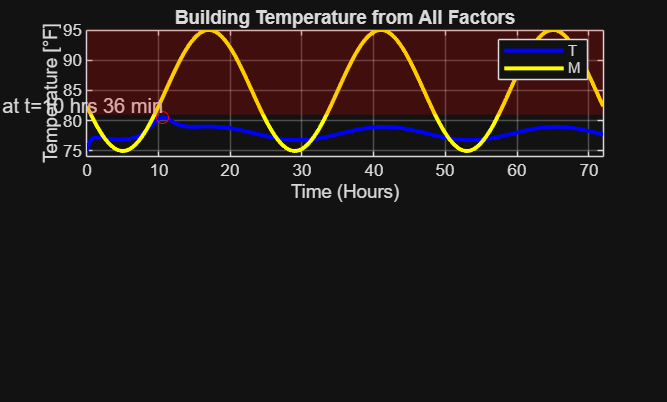

% Parameters
T0 = 75;                    % Initial temperature
t0 = 0;                     % Initial time
tf = 72;                    % Final time
dt = 0.1;                   % Time step
N = floor((tf - t0)/dt);    % Number of steps

% Time vector
t = t0:dt:tf;
T = zeros(1, length(t));    % Preallocate solution
T(1) = T0;                  % Initial condition

% Define internal heat source H(t)
H = @(t, T) 0.25 * (85 - 10 * cos((pi * (t - 5) / 12)) - T) + 7 * sech((3/4)*(t - 10)) + 2*(77-T);    % Heat from people/lights/machines
%          ^^^  Change first value to modify input heat sources

% Define derivative function dT/dt
dTdt = @(t, T) H(t, T);          % No losses, only accumulation

% RK4 Integration
for i = 1:N
    ti = t(i);
    Ti = T(i);

    k1 = dt * dTdt(ti, Ti);
    k2 = dt * dTdt(ti + dt/2, Ti + k1/2);
    k3 = dt * dTdt(ti + dt/2, Ti + k2/2);
    k4 = dt * dTdt(ti + dt, Ti + k3);

    T(i+1) = Ti + (1/6)*(k1 + 2*k2 + 2*k3 + k4);
end

% Find and display max temperature and when it occurs
[max_T, idx_max] = max(T);      % Max value and its index
time_max_T = t(idx_max);        % Time at which max occurs

% Convert time to duration
time_duration = duration(floor(time_max_T), mod(time_max_T*60, 60), 0); % Convert to hours and minutes

% Plot the result
figure;
y_max = max_T + 5; 

% Define M(t)
M = 85 - 10 * cos((pi * (t - 5) / 12));

% Plot temperature T(t) and M(t) function
subplot(2, 1, 1);
plotT = plot(t, T, 'b-', 'LineWidth', 2);
hold on;
plotM = plot(t, M, 'y-', 'LineWidth', 2);
xlabel('Time (Hours)');
ylabel('Temperature [°F]');
title('Building Temperature from All Factors');
xlim([0 72]);        % Fix x-axis to 0–72 hours
ylim([min(T)-1, 95]);  % Pad lower limit slightly for visibility
grid on;
hold off;

% Add text to the graph where max temp occurs
hold on; % Keep the current plot
plot(time_max_T, max_T, 'ro'); % Mark the max temperature point
time_hours = floor(time_max_T); % Get the integer hours
time_minutes = round((time_max_T - time_hours) * 60); % Round minutes to nearest integer
text(time_max_T, max_T, sprintf('Max: %.2f°F at t=%d hrs %d min', max_T, time_hours, time_minutes), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold off; % Release the plot

% Add a red area to denote unsafe temps
hold on;
y_fill = 81 * ones(size(t));
y_max = 95; 
fill([t, fliplr(t)], [y_fill, y_max * ones(size(t))], ...
     'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
hold off;

% Legend
legend([plotT plotM], "T", "M");